## A

First we must load the images:


img_a = imread("./imgs/a_visbileblue.jpg");
img_b = imread("./imgs/b_visiblegreen.jpg");
img_c = imread("./imgs/c_visiblered.jpg");
img_d = imread("./imgs/d_nearinfrared.jpg");
img_e = imread("./imgs/e_middleinfrared.jpg");
img_f = imread("./imgs/f_thermalinfrared.jpg");


We are assuming a grayscale image, so convert them:


img_a = rgb2gray(img_a);
img_b = rgb2gray(img_b);
img_c = rgb2gray(img_c);
img_d = rgb2gray(img_d);
img_e = rgb2gray(img_e);
img_f = rgb2gray(img_f);


Then we convert them to vectors:


vector_a = reshape(img_a, [256*256,1]);
vector_b = reshape(img_b, [256*256,1]);
vector_c = reshape(img_c, [256*256,1]);
vector_d = reshape(img_d, [256*256,1]);
vector_e = reshape(img_e, [256*256,1]);
vector_f = reshape(img_f, [256*256,1]);


Note that these vectors are uint8 due to being images, but we need floating point values - let's convert them to doubles.


vector_a = double(vector_a);
vector_b = double(vector_b);
vector_c = double(vector_c);
vector_d = double(vector_d);
vector_e = double(vector_e);
vector_f = double(vector_f);


Finally we can combine them to a gigantic vector which will be 6x65,536...

vector = [vector_a vector_b vector_c vector_d vector_e vector_f ]'

vector =    255   249   255   255   254   250   251   255   253   255   253   254   254   249   255   251   254   255   250   254   255   254   253   252   253   251   253   255   255   252   252   255   255   248   254   255   254   253   255   253   255   252   255   255   251   254   255   254   254   253
   139   126   131   131   127   130   127   127   111   137   122   119   130   122   132   149   157   173   157   143   145   143   147   150   146   141   149   157   151   146   151   156   141   151   139   127   133   131   127   138   143   145   144   132   127   141   148   136   123   124
    87    80    62    54    89   113    83    53    43    62    66    64    69    71    79    98   105   119   103    84    83    87    91    85    86    82    93    97    83    85    99   102    81    88    75    60    67    75    69    63    85    92    79    61    69    86    86    74    52    55
   208   175   203   187   203   227   206   194   200   195   200   205   196   185   1

Let's find the mean matrix:

mean_matrix = mean(vector,2)

mean_matrix =   108.8263
  110.2227
  108.4957
  157.1799
  141.9874
  109.6162


Now we can find the covariant matrix Cx:

Cx = zeros(6);
for i=1:256*256
    tmp = vector(:,i) - mean_matrix;
    Cx = Cx + (1/(256*256))*(tmp*tmp.');
end
Cx

Cx = 1.0e+03 *

    1.4610    1.2925    1.1335   -0.3030    0.4125    1.0947
    1.2925    1.2832    1.1826   -0.2736    0.4329    1.1341
    1.1335    1.1826    1.3830   -0.3537    0.3605    1.3074
   -0.3030   -0.2736   -0.3537    0.8365    0.3419   -0.3855
    0.4125    0.4329    0.3605    0.3419    0.5007    0.3596
    1.0947    1.1341    1.3074   -0.3855    0.3596    1.3695


Now we find the eigenvalues and eigenvector of our calculated Cx

[eigenvectors, eigenvalues] = eig(Cx)

eigenvectors =     0.3125   -0.4534   -0.0681   -0.6654   -0.0827    0.4925
   -0.6413    0.5152   -0.0615   -0.2757   -0.0969    0.4838
    0.4548    0.2810   -0.5261    0.4365    0.0457    0.4947
   -0.2122   -0.2711   -0.4210    0.1286   -0.8179   -0.1367
    0.3710    0.3267    0.6487    0.0682   -0.5535    0.1542
   -0.3187   -0.5195    0.3415    0.5192    0.0795    0.4859


eigenvalues = 1.0e+03 *

    0.0373         0         0         0         0         0
         0    0.0656         0         0         0         0
         0         0    0.0914         0         0         0
         0         0         0    0.4151         0         0
         0         0         0         0    1.0620         0
         0         0         0         0         0    5.1623


## B

First, we must sort the eigenvectors in descending order of importance/value:

[eigenvalues_ordered, indexes] = sort(diag(eigenvalues), 'descend');
eigenvalues = eigenvalues(indexes, indexes);
eigenvectors = eigenvectors(:,indexes);

A = eigenvectors.'

A =     0.4925    0.4838    0.4947   -0.1367    0.1542    0.4859
   -0.0827   -0.0969    0.0457   -0.8179   -0.5535    0.0795
   -0.6654   -0.2757    0.4365    0.1286    0.0682    0.5192
   -0.0681   -0.0615   -0.5261   -0.4210    0.6487    0.3415
   -0.4534    0.5152    0.2810   -0.2711    0.3267   -0.5195
    0.3125   -0.6413    0.4548   -0.2122    0.3710   -0.3187


y = A*(vector - mean_matrix)

y =    94.0420   42.2146   39.2458   29.5079   51.3708   79.4052   58.3072   28.1726    4.7556   37.1494   31.1972   25.1411   41.2778   39.6043   49.5328   77.8757   84.8275  108.6831   88.7388   62.5460   59.3863   64.4593   70.1994   67.4804   64.2387   55.4288   72.5218   82.3029   67.6309   63.8588   78.0660   88.6353   58.8773   62.8431   49.9367   34.3519   38.4105   44.2661   44.8892   42.0097   61.6681   73.3073   65.5299   39.4748   38.8777   63.7194   68.2909   51.8825   25.4745   23.6991
  -83.3214  -42.3525  -77.3355  -56.0788  -70.8065  -95.2957  -73.6726  -65.1778  -71.4429  -67.7404  -68.1292  -74.3983  -67.8691  -52.6075  -67.8204  -97.0077  -93.0970 -115.2363 -143.0167 -115.5972  -90.0486  -99.4771  -94.0848  -99.3128  -87.8360  -93.8601  -80.3127 -102.4327 -119.5574 -112.2202 -112.3544  -90.2589  -99.7729  -95.0703 -105.4987  -83.2922  -90.2778  -93.6432  -62.9356  -90.4102  -83.2460  -64.4542  -26.6677  -27.3135  -62.6872  -78.8862  -73.5301  -65.3423  -70.7923  -59

Cy = A* Cx * A.'

Cy = 1.0e+03 *

    5.1623    0.0000    0.0000         0   -0.0000   -0.0000
    0.0000    1.0620   -0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000    0.4151    0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000    0.0914   -0.0000   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0656   -0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0373


## C

Now we reform our **y** back to images and display:

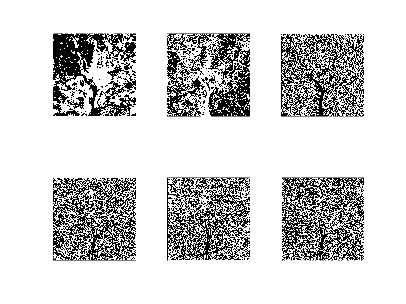

img_a_y = reshape(y(1,:), [256,256]);
img_b_y = reshape(y(2,:), [256,256]);
img_c_y = reshape(y(3,:), [256,256]);
img_d_y = reshape(y(4,:), [256,256]);
img_e_y = reshape(y(5,:), [256,256]);
img_f_y = reshape(y(6,:), [256,256]);

figure
subplot(2,3, 1)
imshow(img_a_y)
subplot(2,3, 2)
imshow(img_b_y)
subplot(2,3, 3)
imshow(img_c_y)
subplot(2,3, 4)
imshow(img_d_y)
subplot(2,3, 5)
imshow(img_e_y)
subplot(2,3, 6)
imshow(img_f_y)